# Lab Activity on descriptive statistics and data visualization

Download from the Files section of the Teams of the course the datafile dataBO.dat, which contains daily temperature (minimum and maximum) and rain recordings in Bologna in 1961-2018.  

Consider in particular both the daily (minimum and maximum) temperature (°C) and average monthly rain (mm) recorded in 2018, and compare them with the average values in the previous 10 years (2008-2017). 

%% 1) Load the data
clear all
close all
clc

% General settings
site = 'Bologna';
month_labels = {'JAN','FEB','MAR','APR','MAY','JUN',...
    'JUL', 'AUG', 'SEP', 'OCT', 'NOV', 'DEC'};

% Select the file containing the data
[filename,path] = uigetfile('*.dat');

if isequal(filename,0)
    disp('User selected Cancel');
    clear all
    return
else
    disp(['User selected ', fullfile(path,filename)]);
end

User selected /home/omismone/dev/MATLAB/abds/lab1/Lab1/dataBO.dat


data = readtable(fullfile(path,filename));

Rain = data.Rain;
Tmax = data.Tmax;
Tmin = data.Tmin;
Tmean = mean([Tmin'; Tmax']);

% The data are saved into a Table object.
% Dates are stored into MATLAB datetime datatypes... Type doc datetime to see how to use it.

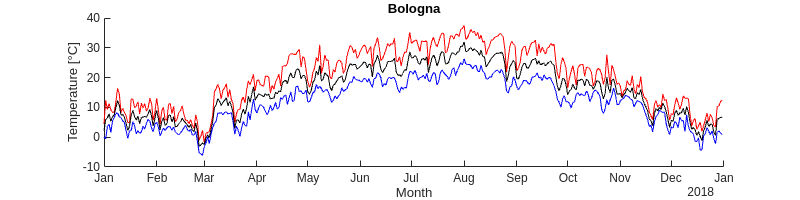

%% 2) Plot 2018 data samples
% select the 2018 data

last_year = 2018;
ind_last = find(year(data.Date) == last_year);
data2018 = data(ind_last,:);

% Use plot() to display the 2018 temperature...
% display the 2018 temperature

figure
set(gcf,'position',[100 100 800 200])
plot(data2018.Date,data2018.Tmin,'b')
hold on
plot(data2018.Date,data2018.Tmax,'r')
plot(data2018.Date,Tmean(ind_last),'k')
xlabel('Month')
ylabel('Temperature [°C]')
title(site)
box off

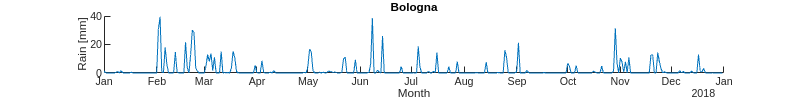


% Use plot() to display the 2018 rain...
% display the 2018 rain

figure
set(gcf,'position',[100 100 800 100])
plot(data2018.Date,data2018.Rain)
xlabel('Month')
ylabel('Rain [mm]')
title(site)
box off

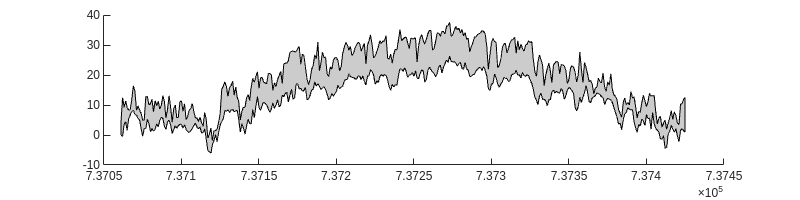


% Use patch() function to plot Tmin and Tmax in 2018 as thick lines..

figure
set(gcf,'position',[100 100 800 200])
patch(datenum([data2018.Date; flipud(data2018.Date)]),...
    [data2018.Tmin; flipud(data2018.Tmax)],[0.8 0.8 0.8])

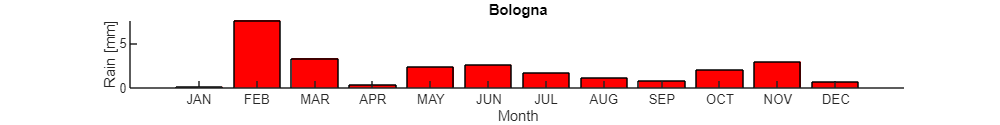

%% 3) Take monthly average

for m = 1:12
    ismonth = find(month(data2018.Date)== m);
    mRain(m) = mean(data2018.Rain(ismonth));
    mTmin(m) = mean(data2018.Tmin(ismonth));
    mTmax(m) = mean(data2018.Tmax(ismonth));
    mTmean(m) = mean(Tmean(ismonth));
end

% Use bar() to display the average monthly rain in 2018

figure
set(gcf,'position',[100 100 800 100])
bar(1:12,mRain,"red")
xlabel('Month')
ylabel('Rain [mm]')
title(site)
box off

% Put month names as labels on X axis

set(gca,'XTickLabel',month_labels)

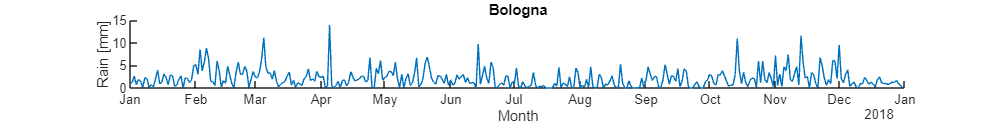

%% 4) Average and plot 2008-2017 data samples
% Eliminate extra days in leap years to make averaging over days easier

data0817 = data(find(year(data.Date)>=2008 & year(data.Date)<=2017),:);
leap_day = find(day(data0817.Date)==29 & month(data0817.Date)==2);
data0817noleap = data0817;
data0817noleap(leap_day,:) = [];

Rain0817 = reshape(data0817noleap.Rain,365,10);
Tmin0817 = reshape(data0817noleap.Tmin,365,10);
Tmax0817 = reshape(data0817noleap.Tmax,365,10);
Date0817 = reshape(data0817noleap.Date,365,10);

% Average data

last10y_Rain = mean(Rain0817,2);
last10y_Tmin = mean(Tmin0817,2);
last10y_Tmax = mean(Tmax0817,2);

% Plot the 10-year average rain data

figure
set(gcf,'position',[100 100 800 100])
plot(data2018.Date,last10y_Rain)
xlabel('Month')
ylabel('Rain [mm]')
title(site)
box off

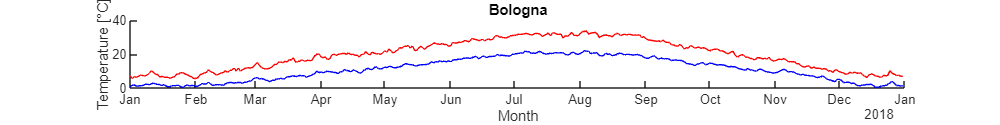


% Plot the 10-year average temperature data (min and max)

figure
set(gcf,'position',[100 100 800 100])
plot(data2018.Date,last10y_Tmin,'b')
hold on
plot(data2018.Date,last10y_Tmax,'r')

xlabel('Month')
ylabel('Temperature [°C]')
title(site)
box off

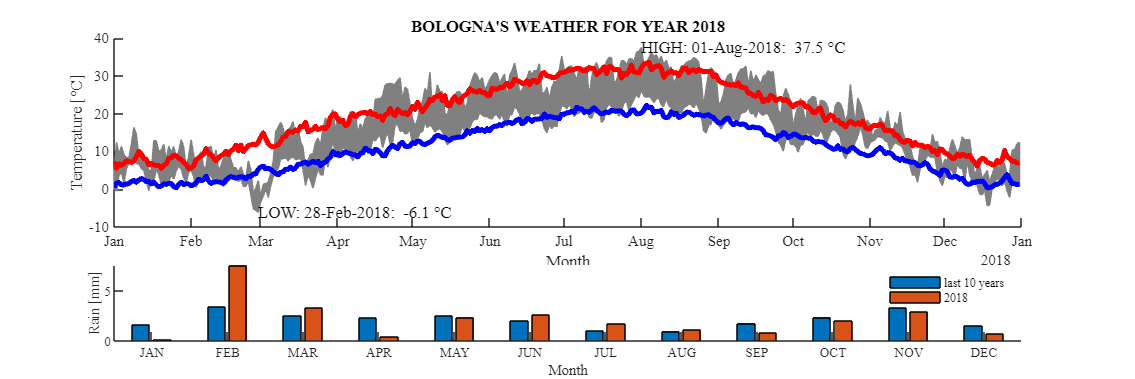

%% 5) Generate a high-quality plot

% Generate a single figure which summarizes the above data.

% Use low-level MATLAB graphics commands and pay special attention to
% Telling the truth;
% Maximising the data ink ratio
% Maximizing the data density
% Create a figure with a suitable aspect ratio

% Create an axis suitable for plotting temperature data

figure
set(gcf,'position',[100 100 1200 400])

ax_temp = axes('position',[0.1 0.4 0.8 0.5]);

%% Plot temperature data

axes(ax_temp)
patchcolor = [0.5 0.5 0.5]; % set patch color here...
hp=patch(([data2018.Date; flipud(data2018.Date)]),...
    [data2018.Tmin; flipud(data2018.Tmax)],patchcolor);
set(hp,'EdgeColor',patchcolor); % this is to eliminate contours from patch

% plot 10-year averages of Tmin and Tmax
line((data2018.Date),last10y_Tmin,'color','b','LineWidth',3)
line((data2018.Date),last10y_Tmax,'color','r','LineWidth',3)

xlabel('Month')
ylabel('Temperature [°C]')
title(sprintf('%s''S WEATHER FOR YEAR %d',upper(site),last_year));

% plot labels for lowest and highest temperatures
[lowestT,lo_indx] = min(data2018.Tmin);
[highestT,hi_indx] = max(data2018.Tmax);
text(data2018.Date(lo_indx), lowestT,  sprintf('LOW: %s: %5.1f °C',datestr(data2018.Date(lo_indx),'dd-mmm-yyyy'),lowestT),'fontname','times')
text(data2018.Date(hi_indx), highestT, sprintf('HIGH: %s: %5.1f °C',datestr(data2018.Date(hi_indx),'dd-mmm-yyyy'),highestT),'fontname','times')

% uses a serif-type font which improves readability
set(gca,'fontname','times')

%% Plot rain data
% Create an axis suitable for rain data
ax_rain = axes('position', [0.1 0.1 0.8 0.2]);

axes(ax_rain)

% calculate monthly average Rain in last 10 years
for m=1:12
    ismonth = find(month(data2018.Date)== m );
    mRain10(m) = mean(last10y_Rain(ismonth));
end

% plot both 2018 and 10-years average rain
bar((1:12)-0.5,[mRain10; mRain])
box off
xlim([0 12])
set(gca,'Xtick',(1:12)-0.5,'XTickLabel',month_labels)
xlabel('Month')
ylabel('Rain [mm]')
legend({'last 10 years','2018'})
legend boxoff

% uses a serif-type font which improves readability
set(gca,'fontname','times')

%% 6) Load a new dataset

% This dataset refers to 30 patients tested across three times 
% to see if there was an improvement in their visual function 
% (the highest value corresponds to the best visual function) after some drug's treatments. 
% The name of data is data_lab1_vis.csv.

clear all
close all

[filename,path] = uigetfile("*.csv");

if isequal(filename,0)
   disp('User selected Cancel');
   clear all
   return
else
   disp(['User selected ', fullfile(path,filename)]);
end

User selected C:\Users\ncartocci\Documents\MEGAsync\Analysis of biomedical data and signals\ABDS\Lab1\data_lab1_vis.csv



data = readtable(fullfile(path,filename));

n_subjects = 30;

c = categorical({'ONE','TWO','THREE'});


%% 7) Mean and standard deviation

% Draw in one plot what is the mean value and the standard error 
% using the simplest way of visualization.


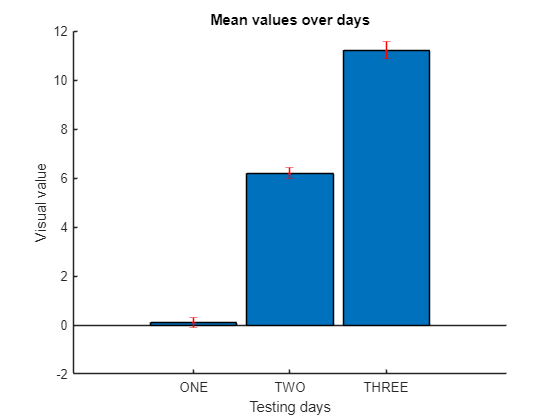

%% 8) Data visualization

% Display a boxplot and a violin plot of data during the three days of treatments.
% Hint of useful functions: boxplot or boxchart, repmat, swarmchart